# **Power Source Control**

The IS506 has three Power Sources (IT6433, IT6431, IT6433). The programing catalog can be seen in.

[IT6411-33-Programming-Guide.pdf (altoo.dk)](https://www.altoo.dk/files/itech/manuals/IT6411-33-Programming-Guide.pdf).

The three Power sources has the following network configuration.

- X-Axis: IT6433, IP: 192.168.0.10, Mask: 255.255.255.0, Gateway:192.168.0.1

- Y-Axis: IT6433, IP: 192.168.0.11, Mask: 255.255.255.0, Gateway:192.168.0.1

- Z-Axis: IT6433, IP: 192.168.0.12, Mask: 255.255.255.0, Gateway:192.168.0.1

The three power sources are connecter with the controller PC through a 5 output swith model: TL-SF1005M. The control computer has the following network configuration:

- Control computer: IP: 192.168.0.20, Mask: 255.255.255.0, Gateway: 192.168.0.1

The three DC founts only work with the socket port 30000 and to send the SCPI comads.

%%%Create TCP/IP object 't'. Specify server machine and port number. 
x_axis = tcpip('192.168.0.10', 30000); %%

%%%Set size of receiving buffer, if needed. 
set(x_axis, 'InputBufferSize', 30000); 

%%%Open connection to the server. 
fopen(x_axis); 

%%%Transmit data to the server (SCPI mode). 
fprintf(x_axis, '*IDN?'); 

%%%Pause for the communication delay, if needed. 
pause(1) 

%%%Receive lines of data from server 
while (get(x_axis, 'BytesAvailable') > 0) 
    x_axis.BytesAvailable 
    DataReceived = fscanf(x_axis) 
end 

%%%Disconnect and clean up the server connection. 
fclose(x_axis); 
delete(x_axis); 
clear x_axis 

To controll the Power DC it is necessary to enter into the remote control mode. This is done with the SCPI command:

The commands to set general parameters like Current and Voltage are SET with the following commands. The CURRent 1.0 value sets the maximun current value, the VOLTage value set the voltage value and the OUTPut ON command turn ON the voltage value.

The Following commands read the voltage, current and power delivered by the power source and measured by the voltimeter and amperimeter inside the power source.

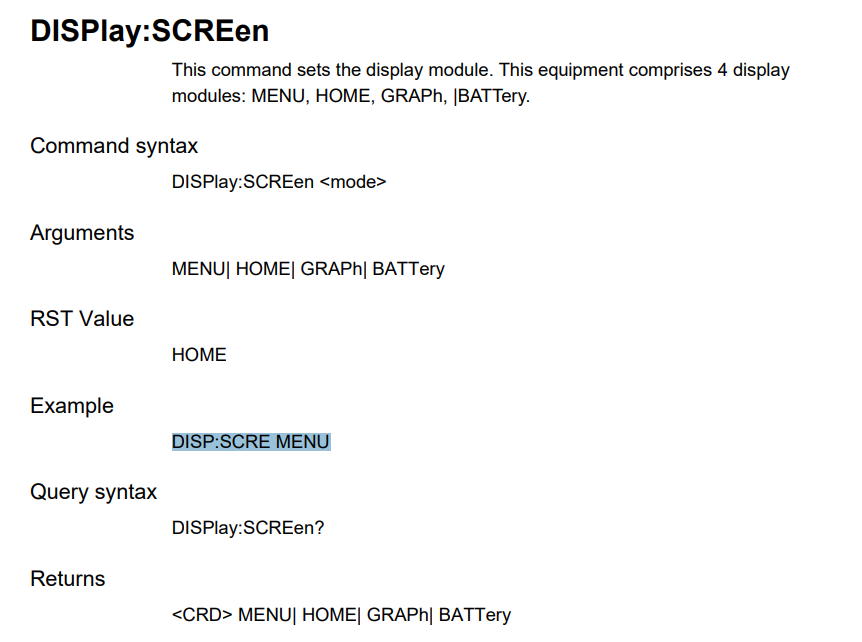

% Create TCP/IP object 't'. Specify server machine and port number. 
x_axis = tcpip('192.168.0.10', 30000); %%

% Set size of receiving buffer, if needed. 
set(x_axis, 'InputBufferSize', 30000); 

% Open connection to the server. 
fopen(x_axis); 

% Pause for the communication delay, if needed. 
pause(1) 

% Transmit data to the server (SCPI mode). 
fprintf(x_axis, 'SYSTem:REMote');
fprintf(x_axis,'DISP:SCRE HOME');
fprintf(x_axis, 'CURRent 1.0');
%fprintf(x_axis, 'VOLTage 12');
fprintf(x_axis, 'OUTPut ON');
fprintf(x_axis, 'MEASure:VOLTage?');

% Receive lines of data from server 
while (get(x_axis, 'BytesAvailable') > 0) 
x_axis.BytesAvailable 
DataReceived = fscanf(x_axis) 
end 

% Disconnect and clean up the server connection. 
fclose(x_axis); 
delete(x_axis); 
clear x_axis 

% Transmit data to the server (SCPI mode). 
fprintf(x_axis, 'SYSTem:LOCal'); 

## Magnetic Coils model

We send different voltages throught the sources in order to dermine the resistance and perform an accurate control.

Preliminarly we measure the resistenance in each coil with the multimeter VICTOR VC980 obtained the following values:

- X-axis: 15.16-15.20 $\Omega$  operating range (-15DCV/ +15DCV).

- Y-axis: 7.80-7.87 $\Omega$ operating range (-7DCV/ +7DCV).

- Z-axis: 13.83-13.88 $\Omega$ operating range (-10DCV/ +10DCV).

For security reasons, the maximun current that we will use in this experiment it is confined from -1A to 1A for each Coil. 

First, we will start the comunication with each coil

%%Data to store the obtained values
x_coil_data = [];
y_coil_data = [];
z_coil_data = [];

% Create TCP/IP object 't'. Specify server machine and port number. 
x_axis = tcpip('192.168.0.10', 30000); 
y_axis = tcpip('192.168.0.11', 30000); 
z_axis = tcpip('192.168.0.12', 30000); 

% Set size of receiving buffer, if needed. 
set(x_axis, 'InputBufferSize', 30000); 
set(y_axis, 'InputBufferSize', 30000); 
set(z_axis, 'InputBufferSize', 30000); 

### For X axis

% Open connection to the server. 
fopen(x_axis); pause(1);

% Send preliminary data
fprintf(x_axis, 'SYSTem:REMote;DISP:SCRE HOME;CURRent 1.0');

figure()
for i = -15:0.1:15
    fprintf(x_axis,['VOLTage ', num2str(i,'%.2f')]);
    %disp(['VOLTage ', num2str(i,'%.2f')]);
    fprintf(x_axis, 'OUTPut ON');
    %%% Require the measured voltage and current
    fprintf(x_axis, 'MEASure:VOLTage?;MEASure:CURRent?');
    pause(0.5);
    %%% Receive lines of data from server 
    while (get(x_axis, 'BytesAvailable') > 0) 
        x_axis.BytesAvailable;
        DataReceived = fscanf(x_axis);
    end  

    if exist('DataReceived','var')
        if (length(DataReceived)>13)
        numDat = sscanf(DataReceived,'%f%f');
        x_coil_data = [x_coil_data, numDat];
        plot(numDat(2), numDat(1),'r.','LineWidth',3');hold on
        xlabel('A'); ylabel('V'); grid on; title('X-Coil Measures')
        end
    end
    pause(2);
end
% Disconnect and clean up the server connection. 
fclose(x_axis); 
delete(x_axis); 
clear x_axis 

xCoilDataFileName = 'xCoil_Epoch_2023_07_09.mat';
save(xCoilDataFileName,'x_coil_data');

In order to characterize the power sources and the resistance of the power sources, we will find the coils resistance. 

%%% Read data measured
fileName = 'xCoil_Epoch_2023_07_09.mat';
load(fileName);

% Perform linear regression of degree 1 (a straight line)
degree_of_polynomial = 1;
coeffs = polyfit(x_coil_data(2,:), x_coil_data(1,:), degree_of_polynomial);

% Coeffs will contain the coefficients of the fitted polynomial (in this case, the slope and intercept)
slope = coeffs(1);
intercept = coeffs(2);

% Plot the data and the linear regression line
figure()
plot(x_coil_data(2,:),x_coil_data(1,:),'r.','LineWidth',3);hold on; % Keep the current plot
ylabel('Voltage(V)'); xlabel('Current(A)'); grid on; title('X-Coil Measures')

x_fit = linspace(min(x_coil_data(2,:)), max(x_coil_data(2,:)), 50); % x values for the regression line
y_fit = polyval(coeffs, x_fit); % Calculate fitted y values
plot(x_fit, y_fit, 'b--','LineWidth',2); % Linear regression line
legend('Data', 'Linear Regression');
grid on; hold off; % Release the plot
% Display the slope and intercept
fprintf('Slope: %.2f, Intercept: %.2f\n', slope, intercept);

The linear regression is described in the following equation.


$$V = slope * I + Intercept$$


And it can be compared with Ohm law wich is described in the following form.


$$V = IR$$


Where $V$ is voltage, $I$ is current and $R$ is the resistor. Due to the intercept is so near to zero, then we can conclude that the slope value is the same that the resistance value. Then: 

% Display the slope and intercept
fprintf('Resistance of the X coil: %.2f omega\n', slope);

For y axis.

% Open connection to the server. 

fopen(y_axis); pause(1);

% Send preliminary data
fprintf(y_axis, 'SYSTem:REMote;DISP:SCRE HOME;CURRent 1.0');

figure()
for i = -7:0.1:7
    fprintf(y_axis,['VOLTage ', num2str(i,'%.2f')]);
    %disp(['VOLTage ', num2str(i,'%.2f')]);
    fprintf(y_axis, 'OUTPut ON');
    %%% Require the measured voltage and current
    fprintf(y_axis, 'MEASure:VOLTage?;MEASure:CURRent?');
    pause(0.5);
    %%% Receive lines of data from server 
    while (get(y_axis, 'BytesAvailable') > 0) 
        y_axis.BytesAvailable;
        DataReceived = fscanf(y_axis);
    end  

    if exist('DataReceived','var')
        if (length(DataReceived)>13)
        numDat = sscanf(DataReceived,'%f%f');
        y_coil_data = [y_coil_data, numDat];
        plot(numDat(2), numDat(1),'b.','LineWidth',3');hold on
        xlabel('A'); ylabel('V'); grid on; title('Y-Coil Measures')
        end
    end
    pause(2);
end

yCoilDataFileName = 'yCoil_Epoch_2023_07_09.mat';
save(yCoilDataFileName,'y_coil_data');

In order to characterize the power sources and the resistance of the power sources, we will find the coils resistance. 

%%% Read data measured
fileName = 'yCoil_Epoch_2023_07_09.mat';
load(fileName);

% Perform linear regression of degree 1 (a straight line)
degree_of_polynomial = 1;
coeffs = polyfit(y_coil_data(2,:), y_coil_data(1,:), degree_of_polynomial);

% Coeffs will contain the coefficients of the fitted polynomial (in this case, the slope and intercept)
slope = coeffs(1);
intercept = coeffs(2);

% Plot the data and the linear regression line
figure()
plot(y_coil_data(2,2:end),y_coil_data(1,2:end),'b.','LineWidth',3);hold on; % Keep the current plot
ylabel('Voltage(V)'); xlabel('Current(A)'); grid on; title('Y-Coil Measures')

x_fit = linspace(min(y_coil_data(2,2:end)), max(y_coil_data(2,2:end)), 50); % x values for the regression line
y_fit = polyval(coeffs, x_fit); % Calculate fitted y values
plot(x_fit, y_fit, 'r--','LineWidth',2); % Linear regression line
legend('Data', 'Linear Regression');
grid on; hold off; % Release the plot
% Display the slope and intercept
fprintf('Slope: %.2f, Intercept: %.2f\n', slope, intercept);

The linear regression is described in the following equation.


$$V = slope * I + Intercept$$


And it can be compared with Ohm law wich is described in the following form.


$$V = IR$$


Where $V$ is voltage, $I$ is current and $R$ is the resistor. Due to the intercept is so near to zero, then we can conclude that the slope value is the same that the resistance value. Then: 

% Display the slope and intercept
fprintf('Resistance of the Y coil: %.2f omega\n', slope);

For the Z

% Open connection to the server. 
fopen(z_axis); pause(1);

% Send preliminary data
fprintf(z_axis, 'SYSTem:REMote;DISP:SCRE HOME;CURRent 1.0');

figure()
for i = -10:0.1:10
    fprintf(z_axis,['VOLTage ', num2str(i,'%.2f')]);
    %disp(['VOLTage ', num2str(i,'%.2f')]);
    fprintf(z_axis, 'OUTPut ON');
    %%% Require the measured voltage and current
    fprintf(z_axis, 'MEASure:VOLTage?;MEASure:CURRent?');
    pause(0.5);
    %%% Receive lines of data from server 
    while (get(z_axis, 'BytesAvailable') > 0) 
        z_axis.BytesAvailable;
        DataReceived = fscanf(z_axis);
    end  

    if exist('DataReceived','var')
        if (length(DataReceived)>13)
        numDat = sscanf(DataReceived,'%f%f');
        z_coil_data = [z_coil_data, numDat];
        plot(numDat(2), numDat(1),'b.','LineWidth',3');hold on
        xlabel('A'); ylabel('V'); grid on; title('Z-Coil Measures')
        end
    end
    pause(2);
end

yCoilDataFileName = 'zCoil_Epoch_2023_07_09.mat';
save(yCoilDataFileName,'z_coil_data');

In order to characterize the power sources and the resistance of the power sources, we will find the coils resistance. 

%%% Read data measured
fileName = 'zCoil_Epoch_2023_07_09.mat';
load(fileName);

% Perform linear regression of degree 1 (a straight line)
degree_of_polynomial = 1;
coeffs = polyfit(z_coil_data(2,:), z_coil_data(1,:), degree_of_polynomial);

% Coeffs will contain the coefficients of the fitted polynomial (in this case, the slope and intercept)
slope = coeffs(1);
intercept = coeffs(2);

% Plot the data and the linear regression line
figure()
plot(z_coil_data(2,2:end),z_coil_data(1,2:end),'r.','LineWidth',3);hold on; % Keep the current plot
ylabel('Voltage(V)'); xlabel('Current(A)'); grid on; title('Z-Coil Measures')

x_fit = linspace(min(z_coil_data(2,2:end)), max(z_coil_data(2,2:end)), 50); % x values for the regression line
y_fit = polyval(coeffs, x_fit); % Calculate fitted y values
plot(x_fit, y_fit, 'b--','LineWidth',2); % Linear regression line
legend('Data', 'Linear Regression');
grid on; hold off; % Release the plot
% Display the slope and intercept
fprintf('Slope: %.2f, Intercept: %.2f\n', slope, intercept);

The linear regression is described in the following equation.


$$V = slope * I + Intercept$$


And it can be compared with Ohm law wich is described in the following form.


$$V = IR$$


Where $V$ is voltage, $I$ is current and $R$ is the resistor. Due to the intercept is so near to zero, then we can conclude that the slope value is the same that the resistance value. Then: 

% Display the slope and intercept
fprintf('Resistance of the Z coil: %.2f omega\n', slope);

## Get Real Mode

We will send step voltage in each coil and then we will measure the magnetic field to see the behavior.

### **X axis**

Start conection with the sensor.

disp("Display available Serial Ports:");
availableSerialPorts = IDSerialComs("available");
disp(availableSerialPorts);

Then we checked the name USB-SERIAL CH430 and a serial object is necesary to be created.

for i = 1:size(availableSerialPorts,1)
    if strcmp('USB-SERIAL CH340',availableSerialPorts{i,1})
        try
            s = serialport(availableSerialPorts{i,2},9600);
            disp('Port connected sucessfully.');
        catch Err
            disp(Err.message);
        end
    end
end

Start conexion with the Power sources

% Create TCP/IP object 't'. Specify server machine and port number. 
x_axis = tcpip('192.168.0.10', 30000);
% Set size of receiving buffer, if needed. 
set(x_axis, 'InputBufferSize', 30000); 
% Open connection to the server. 
fopen(x_axis); pause(1);
% Start Remote operation and set as maximum current 1A.
fprintf(x_axis, 'SYSTem:REMote;DISP:SCRE HOME;CURRent 1.0');

Start measurements with voltage ramps.

figure()
x_coil_data_mag = [];
ts =tic;
for i = -15:0.1:15
    t1 = toc(ts);
    fprintf(x_axis,['VOLTage ', num2str(i,'%.2f')]);
    %disp(['VOLTage ', num2str(i,'%.2f')]);
    fprintf(x_axis, 'OUTPut ON');
    %%% Require the measured voltage and current
    fprintf(x_axis, 'MEASure:VOLTage?;MEASure:CURRent?');
    pause(0.5);
    %%% Receive lines of data from server 
    while (get(x_axis, 'BytesAvailable') > 0) 
        x_axis.BytesAvailable;
        DataReceived = fscanf(x_axis);
    end  

    if exist('DataReceived','var')
        if (length(DataReceived)>13)
        numDat = sscanf(DataReceived,'%f%f');
        %x_coil_data = [x_coil_data, numDat];
        rawData = read(s,27,"string");
        actualMeasures = sscanf(rawData,'%fA%fB%fC');
        x_coil_data_mag = [x_coil_data_mag, vertcat(t1,numDat,actualMeasures)];
        subplot(2,1,1)
            plot(numDat(2), numDat(1),'r.','LineWidth',3');hold on
            xlabel('A'); ylabel('V'); grid on; title('X-Coil Measures')
        subplot(2,1,2)
            h1=plot(i, actualMeasures(1),'r.','LineWidth',3'); hold on;
            h2=plot(i, actualMeasures(2),'b.','LineWidth',3'); 
            h3=plot(i, actualMeasures(3),'g.','LineWidth',3'); grid on;
            xlabel('V'); ylabel('nT'); title('Magnetic Field');
            legend([h1,h2,h3],'X','Y','Z');
        end
    end
    pause(3);
end

Close all ports.

fclose(x_axis); 
delete(x_axis); 
clear x_axis 
delete(s)

xCoilDataFileNameMag = 'zCoil_mag_Epoch_2023_14_09.mat';
save(xCoilDataFileNameMag,'x_coil_data_mag');

For the Y axis

Start conexion with the Power sources

% Create TCP/IP object 't'. Specify server machine and port number. 
y_axis = tcpip('192.168.0.11', 30000);
% Set size of receiving buffer, if needed. 
set(y_axis, 'InputBufferSize', 30000); 
% Open connection to the server. 
fopen(y_axis); pause(1);
% Start Remote operation and set as maximum current 1A.
fprintf(y_axis, 'SYSTem:REMote;DISP:SCRE HOME;CURRent 1.0');

figure()
y_coil_data_mag = [];
for i = -7:0.1:7
    fprintf(y_axis,['VOLTage ', num2str(i,'%.2f')]);
    %disp(['VOLTage ', num2str(i,'%.2f')]);
    fprintf(y_axis, 'OUTPut ON');
    %%% Require the measured voltage and current
    fprintf(y_axis, 'MEASure:VOLTage?;MEASure:CURRent?');
    pause(0.5);
    %%% Receive lines of data from server 
    while (get(y_axis, 'BytesAvailable') > 0) 
        y_axis.BytesAvailable;
        DataReceived = fscanf(y_axis);
    end  

    if exist('DataReceived','var')
        if (length(DataReceived)>13)
        numDat = sscanf(DataReceived,'%f%f');
        %x_coil_data = [x_coil_data, numDat];
        rawData = read(s,27,"string");
        actualMeasures = sscanf(rawData,'%fA%fB%fC');
        y_coil_data_mag = [y_coil_data_mag, vertcat(numDat,actualMeasures)];
        subplot(2,1,1)
            plot(numDat(2), numDat(1),'r.','LineWidth',3');hold on
            xlabel('A'); ylabel('V'); grid on; title('Y-Coil Measures')
        subplot(2,1,2)
            h1=plot(i, actualMeasures(1),'r.','LineWidth',3'); hold on;
            h2=plot(i, actualMeasures(2),'b.','LineWidth',3'); 
            h3=plot(i, actualMeasures(3),'g.','LineWidth',3'); grid on;
            xlabel('V'); ylabel('nT'); title('Magnetic Field');
            legend([h1,h2,h3],'X','Y','Z');
        end
    end
    pause(3);
end

yCoilDataFileNameMag = 'yCoil_mag_Epoch_2023_14_09.mat';
save(yCoilDataFileNameMag,'y_coil_data_mag');

For the Z axis

Start conexion with the Power sources

% Create TCP/IP object 't'. Specify server machine and port number. 
z_axis = tcpip('192.168.0.12', 30000); 
% Set size of receiving buffer, if needed. 
set(z_axis, 'InputBufferSize', 30000); 
% Open connection to the server. 
fopen(z_axis); pause(1);
% Start Remote operation and set as maximum current 1A.
fprintf(z_axis, 'SYSTem:REMote;DISP:SCRE HOME;CURRent 1.0');

Start measurements with voltage ramps.

figure()
z_coil_data_mag = [];
for i = -10:0.1:10
    fprintf(z_axis,['VOLTage ', num2str(i,'%.2f')]);
    %disp(['VOLTage ', num2str(i,'%.2f')]);
    fprintf(z_axis, 'OUTPut ON');
    %%% Require the measured voltage and current
    fprintf(z_axis, 'MEASure:VOLTage?;MEASure:CURRent?');
    pause(1);
    %%% Receive lines of data from server 
    while (get(z_axis, 'BytesAvailable') > 0) 
        z_axis.BytesAvailable;
        DataReceived = fscanf(z_axis);
    end  

    if exist('DataReceived','var')
        if (length(DataReceived)>13)
        numDat = sscanf(DataReceived,'%f%f');
        %x_coil_data = [x_coil_data, numDat];
        rawData = read(s,27,"string");
        actualMeasures = sscanf(rawData,'%fA%fB%fC');
        z_coil_data_mag = [z_coil_data_mag, vertcat(numDat,actualMeasures)];
        subplot(2,1,1)
            plot(numDat(2), numDat(1),'r.','LineWidth',3');hold on
            xlabel('A'); ylabel('V'); grid on; title('X-Coil Measures')
        subplot(2,1,2)
            h1=plot(i, actualMeasures(1),'r.','LineWidth',3'); hold on;
            h2=plot(i, actualMeasures(2),'b.','LineWidth',3'); 
            h3=plot(i, actualMeasures(3),'g.','LineWidth',3'); grid on;
            xlabel('V'); ylabel('nT'); title('Magnetic Field');
            legend([h1,h2,h3],'X','Y','Z');
        end
    end
    pause(3);
end

zCoilDataFileNameMag = 'zzCoil_mag_Epoch_2023_14_09.mat';
save(zCoilDataFileNameMag,'z_coil_data_mag');

Now we set step data records:

X axis

Start conexion with the Power sources

% Create TCP/IP object 't'. Specify server machine and port number. 
x_axis = tcpip('192.168.0.10', 30000);
% Set size of receiving buffer, if needed. 
set(x_axis, 'InputBufferSize', 30000); 
% Open connection to the server. 
fopen(x_axis); pause(1);
% Start Remote operation and set as maximum current 1A.
fprintf(x_axis, 'SYSTem:REMote;DISP:SCRE HOME;CURRent 1.0');

Create step voltage from 0 - 5V, 5 - 7 and from 0 - -5 V, -5 -7

x_coil_data_mag_step = [];
j = 0;
ts =tic;

figure()
for i = [0 -10 -5 0 10 5 0]
    t = 0;
    tic;
    while (t < 120)
        t1 = toc(ts);
        t = toc;
        fprintf(x_axis,['VOLTage ', num2str(i,'%.2f')]);
        %disp(['VOLTage ', num2str(i,'%.2f')]);
        fprintf(x_axis, 'OUTPut ON');
        %%% Require the measured voltage and current
        fprintf(x_axis, 'MEASure:VOLTage?;MEASure:CURRent?');
        pause(1);
        %%% Receive lines of data from server 
        while (get(x_axis, 'BytesAvailable') > 0) 
            x_axis.BytesAvailable;
            DataReceived = fscanf(x_axis);
        end  

        if exist('DataReceived','var')
            if (length(DataReceived)>13)
                numDat = sscanf(DataReceived,'%f%f');
                %x_coil_data = [x_coil_data, numDat];
            else
                numDat = sscanf(DataReceived,'%f');
                numDat = [0;numDat];
            end
            rawData = read(s,27,"string");
            actualMeasures = sscanf(rawData,'%fA%fB%fC');
            x_coil_data_mag_step = [x_coil_data_mag_step, vertcat(t1,numDat,actualMeasures)];
            subplot(3,1,1)
                plot(t1, numDat(1),'r.','LineWidth',3');hold on
                xlabel('t'); ylabel('V'); grid on; title('X-Coil Measures')
            subplot(3,1,2)
                plot(t1, numDat(2),'r.','LineWidth',3');hold on
                xlabel('t'); ylabel('A'); grid on; title('X-Coil Measures')
            subplot(3,1,3)
                h1=plot(t1, actualMeasures(1),'r.','LineWidth',3'); hold on;
                h2=plot(t1, actualMeasures(2),'b.','LineWidth',3'); 
                h3=plot(t1, actualMeasures(3),'g.','LineWidth',3'); grid on;
                xlabel('t'); ylabel('nT'); title('Magnetic Field');
                legend([h1,h2,h3],'X','Y','Z');
        end
         pause(3);

    end
end

function [h1,h2] = plotVector(v0,v,scale,style,label,labelLocation)
    if labelLocation=='m'
        scale = scale*1.1;
        h1 = quiver3(v0(1), v0(2), v0(3), v(1)*scale, v(2)*scale, v(3)*scale, style);
        h2 = text(v0(1)+v(1)*scale/2,v0(2)+v(2)*scale/2, v0(3)+v(3)*scale/2, label,'Color',style(1));
    else
        h1 = quiver3(v0(1)*scale, v0(2)*scale, v0(3)*scale, v(1)*scale, v(2)*scale, v(3)*scale, style);
        h2 = text((v0(1)+v(1))*scale, (v0(2)+v(2))*scale, (v0(3)+v(3))*scale, label,'Color',style(1));
    end
    
    Set equal axis scales and display grid
    axis equal
    grid on
end
